omega0 = 2*pi*110; % angular frequency corresponding to 110 Hz
a = 1.5; % Decay rate (per second)
t = 0:1/44.1e3:3; % Time variable
% Compute y here
tc = 0.5; % Cutoff time
% Compute yc here
yc = heaviside(t-tc).*exp(-a.*(t-tc)).*sin(omega0.*t); 
env =  heaviside(t-tc).*exp(-a.*(t-tc)); 

**Task 4. **Plot `yc` against `t` to view the signal in the time domain. What do you expect this signal will look like in the frequency domain?

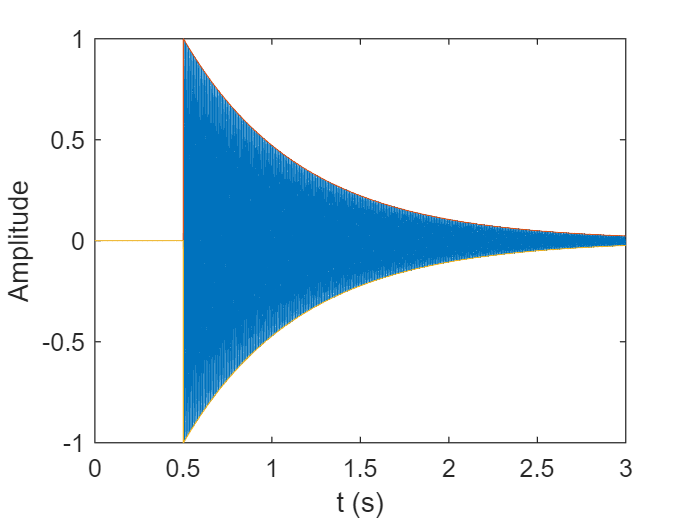

% Create your plot here
plot(t,yc,t,env,t,-env)
xlabel("t (s)")
ylabel("Amplitude")